# **ENG 1101 Project 2: Computational Sensor- Ultrasonic Based 180 Degree 'Radar'**

This project makes use of the ultrasonic sensor included in the arduino kit as well as the servo motor to rotate the sensor 180 degrees, and take measurement data of anything the sensor might see. It then plots this data on a polar (r, theta) graph. All data points are saved into vectors, and while they are removed from the plot after a period of time, they remain stored in memory.

The code below is setup to run based on this wiring diagram: 

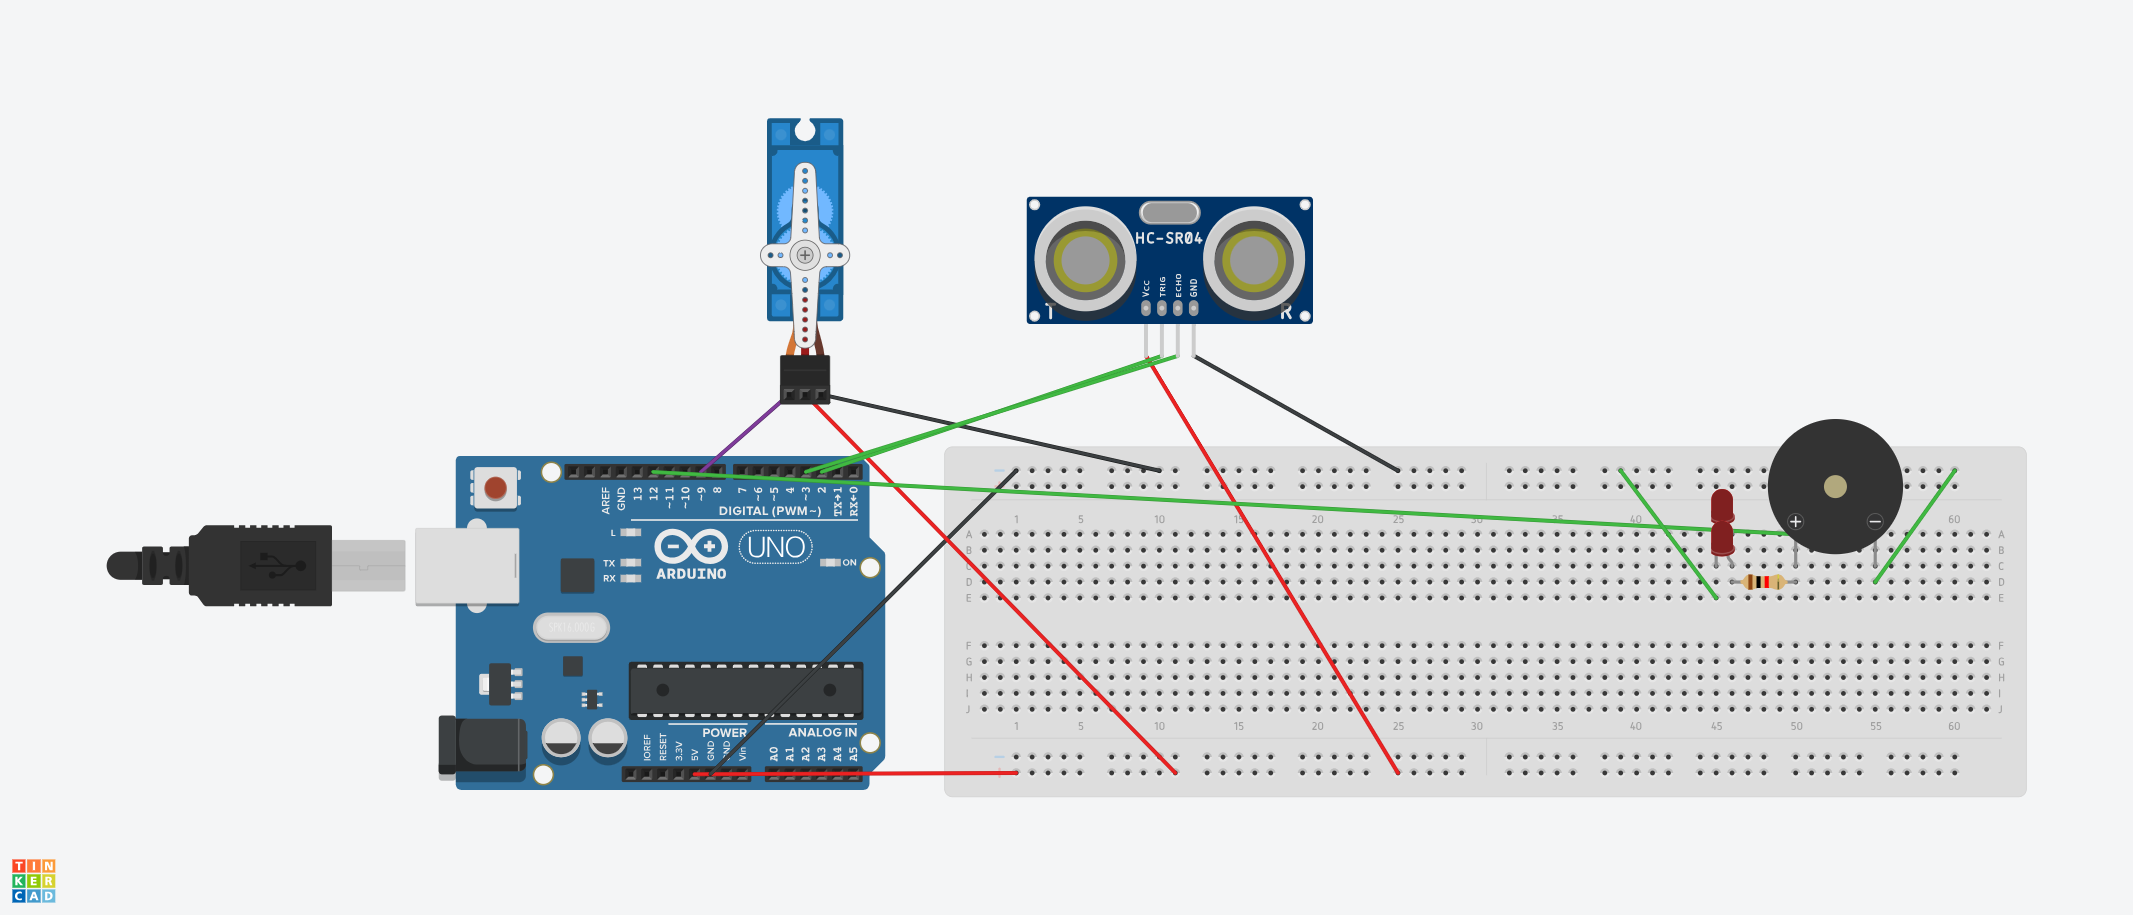

In order to make use of this sensor, wire the servo and arduino as setup above. The LEDs and buzzer are additional, optional features that will not impact the provided code if not implemented. Once the sensor and servo are setup, you are then able to attach the sensor to the servo, through a platform of some sort. Anything from a piece of cardboard to a 3d-printed specific part will acomplish this task. Then, run this code and place an object in front of the sensor. Notice how plotted points appear on the graph, either green or red depending on the distance from the sensor. The sensor itselft seems fairly consistent from within a 1 meter range, so that is what the code below is using, capping the graph's r-axis at 1 meter and using a 'close distance' threshold of 25 centimeters. Both of these values could be adjusted according to the quality of the sensor being used. On an additional note, to explain the lack of '360' movement, this was simply a choice made due to the servo motor provided by the arduino kit being a more 'accurate' and smooth movement than the stepper motor for our purposes of moving small increments of degrees. 

%%Program Name: Project 2
%%Program Description: Ultrasonic Radar using ultrasonic sensor and a servo
%%motor
%%Date of Creation: 10-26-2025

%%Name: Brandon Early
%%Section: R38
%%Team: 4

%clear variables, command windown, etc.
clear %%clears workspace
clc %%clears command window
close all %%closes all figures

% Connect to Arduino and setup
a = arduino('COM4', 'Uno', 'Libraries', {'Servo', 'Ultrasonic'});
s = servo(a, 'D4');
u = ultrasonic(a, 'D2', 'D3');
angles = [];
distances = [];
times = [];
timeStart = tic;

%setting up the 'radar' plot    
figure('Visible', 'on', 'WindowStyle', 'normal');
graph = polaraxes;
rlim([0 1]); %capping the measurements at 1 meter, can be expanded but idk how good this ultrasonic sensor is
thetalim([0 180]); %capping the angles at 180 for the servo
graph.ThetaZeroLocation = 'right'; %preference
graph.ThetaDir = 'counterclockwise'; %adjust based on zero location

%make it look pretty, RGB codes
graph.Color = 'k';
graph.GridColor = [0 1 0]; 
graph.RColor = [0 1 0];
graph.ThetaColor = [0 1 0];
hold on;

%rest of the housekeeping
pointsFar = polarplot(graph, 0, 0, 'g.', 'MarkerSize', 10);
pointsClose = polarplot(graph, 0, 0, 'r.', 'MarkerSize', 10);
count = 0;
last_angle_count = -Inf;
scan = polarplot(graph, 0, 0, 'Color', [0 1 0], 'LineWidth', 2); % sweeping line visual
title('Ultrasonic Radar');
hold on;

x = 1;

while(x > 0)

    % Sweep servo from 0 to 180 degrees
    for(angle = 0:3:180)

        %moving the servo
        writePosition(s, angle / 180);  %servo position is range of 0–1
        pause(0.05); %for smoother movement
        
        %take distance measurement
        dist = readDistance(u);
        dist = min(dist, 1); %% max range of 1m, adjust as needed with sensor capabilites

        %if distance is within threshold, turn on the LED/Buzzer
        if(dist < .25)
            a.writeDigitalPin("D12", 1);
        else
            a.writeDigitalPin("D12", 0);
        end

        %appending measurements to the data collection arrays
        angles = [angles; deg2rad(angle)];
        distances = [distances; dist];
        times = [times; toc(timeStart)];
        
        %check recency of measurements to avoid plot clutter after a while
        %removed the clutter and added single loop instead of whiletrue
        % VALUES ARE STILL IN ARRAY
        recent = (toc(timeStart));

        %check distance measurement to see if within 'close' threshold
        %(arbitrary but im setting baseline at .25 meters)
        close = recent & (distances < .25);
        far = recent & (distances >= .25);

        %plotting data
        set(pointsFar, 'ThetaData', angles(far), 'RData', distances(far));
        set(pointsClose, 'ThetaData', angles(close), 'RData', distances(close));
        set(scan, 'ThetaData', [deg2rad(angle), deg2rad(angle)], 'RData', [0 1]); %updating the radar line, polarplot expects 2d vectors
        drawnow;
    end

    % Back the other way
    for(angle = 180:-3:0)

        %moving the servo
        writePosition(s,angle/180);
        pause(0.05); %for smoother movement

        %take distance measurement
        dist = readDistance(u);
        dist = min(dist, 1);

        %if distance is within threshold, turn on the LED/Buzzer
        if(dist < .25)
            a.writeDigitalPin("D12", 1);
        else
            a.writeDigitalPin("D12", 0);
        end

        %%appending measurements to the data collection arrays
        angles = [angles; deg2rad(angle)];
        distances = [distances;dist];
        times = [times; toc(timeStart)];
        
        %check recency of measurements to avoid plot clutter after a while
        %removed the clutter and added single loop instead of whiletrue
        %VALUES ARE STILL IN ARRAY
        recent = (toc(timeStart));

        %check distance measurement to see if within 'close' threshold
        %(arbitrary but im setting baseline at .25 meters)
        close = recent & (distances < .25);
        far = recent & (distances >= .25);
    
        %plotting data
        set(pointsFar, 'ThetaData', angles(far), 'RData', distances(far));
        set(pointsClose, 'ThetaData', angles(close), 'RData', distances(close));
        set(scan, 'ThetaData', [deg2rad(angle), deg2rad(angle)], 'RData', [0 1]); %updating radar line, polarplot expects 2d vectors
        drawnow;
 
    end
    x = x -1;
end

% Calculate and display average distance and median distance
avgDistance = round(mean(distances) * 100);
medianDistance = round(median(distances) * 100);
fprintf("Median Distance of Points: %.2f cm\n", medianDistance);

Median Distance of Points: 43.00 cm


fprintf("Average Distance of Points: %.2f cm", avgDistance);

Average Distance of Points: 48.00 cm


%count/predicted people logic
for(i = 1:length(distances))
    if(distances(i) < .25 && abs(angles(i) - last_angle_count) > deg2rad(30))
        count = count +1;
        last_angle_count = angles(i);
    end
end

count = count / 2; %%because we 'sweep' back the other direction, it will almost always count the same object twice
fprintf("Estimated Number of People in the Area: %.0f ", count);

Estimated Number of People in the Area: 2 

Example Output Plot:

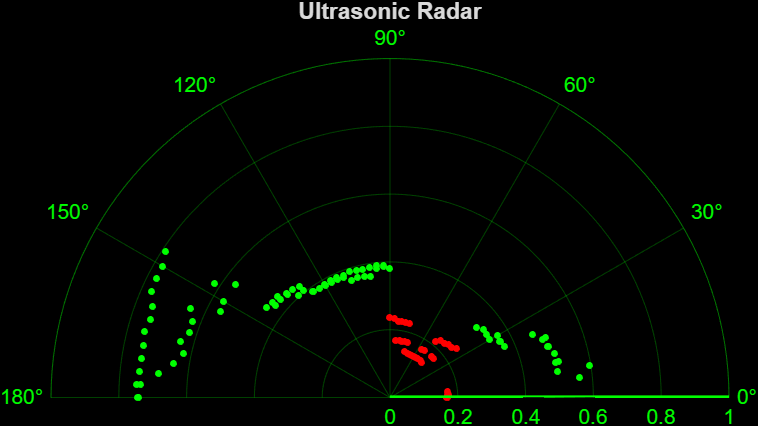

This is the graph created from taking exactly 180 measurements around 180 degrees, as you can see, there is an object at about half a meter between 0 and 30 degrees, an object closer than 25 cm between about 35 and 90 degrees, an object again at about .6 meters from 90 to about 150 degrees, and then an object at about .8 meters from 150 to 180 degrees. 